# Test epigenome-scale metabolic reconstructions

**Author**: Scott Campit

## Summary

This notebook performs a fast diagnostic evaluation of the epigenome-scale metabolic reconstruction. Nutrient perturbation tests are performed to evaluate the connectivity between various metabolic pathways and histone methylation and acetylation.

clear all;
initCobraToolbox(false); changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...usage: git submodule [--quiet] [--cached]
   or: git submodule [--quiet] add [-b <branch>] [-f|--force] [--name <name>] [--reference <repository>] [--] <repository>

 Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: /home/scampit/Software/gurobi903
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...gurobi
ibm_cplex
tomlab_cplex
glpk
mosek
matlab
pdco
quadMinos
dqqMinos
cplex_direct
cplexlp
qpng
tomlab_snopt
lp_solve
 Done.
 > Setting default solve

## 1. Evaluate RECON1 metabolic reconstruction

This specify hyperparameters for the Gurobi optimization step for all metabolic model simulations.

% Set up hyperparameters for the linear programming section
hyperparams.eps = [];  hyperparams.isgenes = true;
hyperparams.kap = [];  hyperparams.eps2 = [];
hyperparams.rho = [];  hyperparams.pfba = false;
hyperparams.kap2 = []; hyperparams.gamma =[];
hyperparams.hscore = false;

### Baseline RECON1 growth rate

First, we'll test the base human metabolic reconstructions to see if they output a feasible growth rate. If so, then we can add the epigenome-scale metabolic reactions to the model.

load /home/scampit/Data/Reconstructions/RECON1/recon1.mat

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(recon1.rxns, {'ALR', 'MGSA', 'MGSA2'}));
recon1.ub(posToTurnOff) = 0; recon1.lb(posToTurnOff) = 0;

% Set growth rate to be from 0 to 1000
recon1.lb(3743) = 0;

% Solve using flux balance analysis
soln = optimizeCbModel(recon1);
grate = soln.x(3743)

grate = 1.1339

### Baseline RECON1 histone methylation flux

RECON1 contains histone methylation reactions. So let's perform several experiments to evaluate how well the model can capture methylation flux without transcriptomics.

#### Titrate different objective coefficients for histone methylation

We'll evaluate how different epsilon values change the metabolic flux for histone mono-, di-, and trimethylation.

% Different epsilon values to simulate methylation flux through.
epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1];

% Simulate metabolic fluxes for each  epsilon value   
dm_metabolites = {"Nmelys_n", "Ndmelys_n", "Ntmelys_n"};
flux           = zeros(length(epsilon), length(dm_metabolites));
grates         = zeros(length(epsilon), length(dm_metabolites));

Simulate metabolic fluxes across different epsilon values and methylation reactions

% Iterate through histone methylation statuses
for i = 1:length(dm_metabolites)
    tmp = recon1;
    tmp = addDemandReaction(tmp, char(dm_metabolites{i}));
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(length(tmp2.rxns)) = epsilon(j);
        [~, soln] = CFR(tmp2, hyperparams, {}, {});
        flux(j, i) = soln.x(length(tmp2.rxns));
    end
end

Let's plot the results for simulating methylation on the base metabolic model in RECON1.

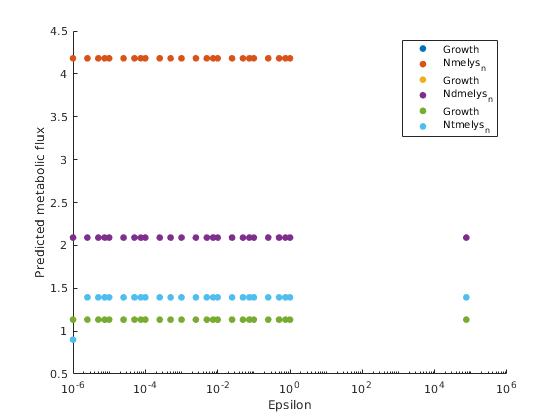

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('Epsilon'); ylabel('Predicted metabolic flux');
legend; 

#### Titrate methionine levels in RECON1

We'll see the impact of modifying the methionine substrate uptake rate and its impact on methylation.

epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1, 10, 100, 1000];

% Iterate through histone methylation statuses
[~, pos] = ismember({'EX_met_L_e'}, recon1.rxns);
for i = 1:length(dm_metabolites)
    tmp = recon1;
    tmp = addDemandReaction(tmp, char(dm_metabolites{i}));
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(length(tmp2.rxns)) = 0.069;
        tmp2.lb(pos) = -epsilon(j);
        
        % Get metabolic flux
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(length(tmp2.rxns));
        catch ME
            flux(j, i) = NaN;
        end
        
    end
end

#### Plot methionine titration

Now let's evaluate how the Methionine substrate uptake rate affects histone methylation in RECON1. It looks like the methylation fluxes plateau after -10 umol / gDW*hr.

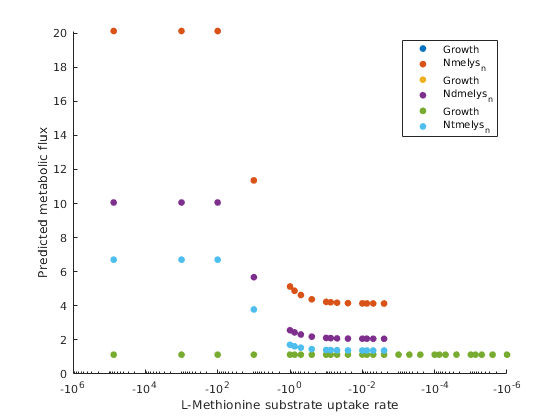

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(-1*epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(-1*epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('L-Methionine substrate uptake rate'); ylabel('Predicted metabolic flux');
legend; 

## 2. Evaluate acetylation metabolic reconstruction from Shen et al., 2019 (AC1)

### Baseline AC1 growth rate

We'll evaluate the growth rate and acetylation flux from the acetylation metabolic reconstruction in Shen et al., 2019.

load /home/scampit/Data/Reconstructions/Acetylation/Acetylation.mat;
% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(acetylation_model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
acetylation_model.ub(posToTurnOff) = 0; acetylation_model.lb(posToTurnOff) = 0;

% Update IDs
acetylation_model.mets = strrep(acetylation_model.mets, '[', '_');
acetylation_model.mets = strrep(acetylation_model.mets, ']', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');
acetylation_model.mets = regexprep(acetylation_model.mets, '-L_', '__L_');
acetylation_model.mets = regexprep(acetylation_model.mets, '-D_', '__D_');

acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');
acetylation_model.rxns = regexprep(acetylation_model.rxns, '_L_', '__L_');
acetylation_model.rxns = regexprep(acetylation_model.rxns, '_D_', '__D_');
acetylation_model.rxns = regexprep(acetylation_model.rxns, '_R_', '__R_');
acetylation_model.rxns = regexprep(acetylation_model.rxns, '_S_', '__S_');

acetylation_model.rxns = regexprep(acetylation_model.rxns, '____', '__');
acetylation_model.rxns = regexprep(acetylation_model.rxns, '___', '__');

% Set growth rate to be from 0 to 1000
acetylation_model.lb(3743) = 0;
soln = optimizeCbModel(acetylation_model);
grate = soln.x(3743)

grate = 1.1339

### Baseline AC1 histone acetylation flux

AC1 contains histone methylation reactions. So let's perform several experiments to evaluate how well the model can capture methylation flux without transcriptomics.

#### Titrate different objective coefficients for histone methylation

We'll evaluate how different epsilon values change the metabolic flux for histone acetylation.

% Different epsilon values to simulate acetylation flux through.
epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1];

% Simulate metabolic fluxes for each  epsilon value   
dm_metabolites = "Naclys_n";
flux           = zeros(length(epsilon), length(dm_metabolites));
grates         = zeros(length(epsilon), length(dm_metabolites));

Simulate metabolic fluxes across different epsilon values and the bulk acetylation reaction

% Iterate through histone acetylation statuses
for i = 1:length(dm_metabolites)
    tmp = acetylation_model;
    
    % Iterate through epislon values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        
        % Acetylation reaction in AC1
        tmp2.lb(3754) = 0;
        tmp2.c(3754) = epsilon(j);
        
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(3754);
        catch ME
            flux(j, i) = NaN;
        end
    end
end

Let's plot the results for simulating acetylation on the base acetylation model. It looks like acetylation is not particularly sensitive to the epsilon parameter.

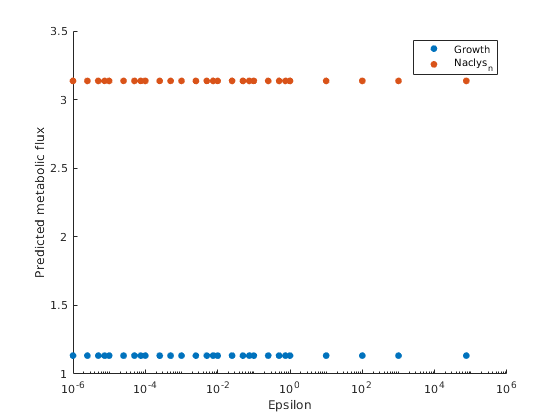

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('Epsilon'); ylabel('Predicted metabolic flux');
legend; 

#### Titrate glucose levels in AC1

We'll see the impact of modifying the methionine substrate uptake rate and its impact on methylation.

epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1, 10, 100, 1000];

% Iterate through histone acetylation statuses
for i = 1:length(dm_metabolites)
    tmp = acetylation_model;
    tmp = addDemandReaction(tmp, char(dm_metabolites{i}));
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        posgluc = find(ismember(tmp.rxns, 'EX_glc_e'));
        tmp.lb(posgluc) = -epsilon(j);
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(3754) = 1E-3;
        
        % Get metabolic flux
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(3754);
        catch ME
            flux(j, i) = NaN;
        end
        
    end
end

#### Plot glucose titration

Now let's evaluate how the glucose substrate uptake rate affects histone acetylation in AC1. It looks like the acetylation fluxes plateau after -10 umol / gDW*hr.

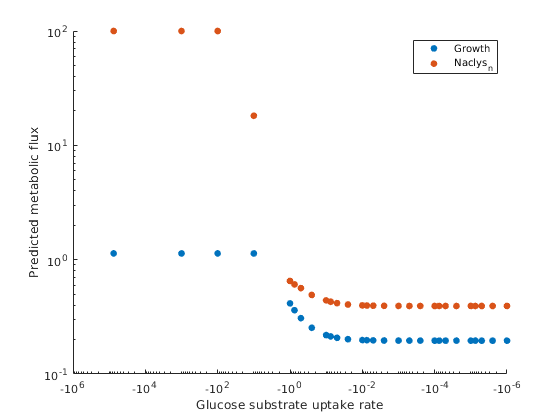

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(-1*epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(-1*epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log', 'YScale', 'log')
xlabel('Glucose substrate uptake rate'); ylabel('Predicted metabolic flux');
legend; 

## 3. Evaluate new methylation model

This histone methylation metabolic reconstruction was made after extensive literature curation. The notebook showing the steps to making this complete reconstruction can be found in `/Reconstruction/eGEM_construction.mlx`.

### Complete methylation reconstruction growth rate

We're going to see if the growth rate changes between the original metabolic model and this complete eGEMM reconstruction.

load /home/scampit/Data/Reconstructions/eGEM/10262020_methylation.mat; % Latest version of eGEM model
soln = optimizeCbModel(eGEM);
grate = soln.x(3743)

### Methylation model histone methylation flux

Let's perform several experiments to evaluate how well the methylation reconstruction can capture methylation flux without transcriptomics.

#### Titrate different objective coefficients for histone methylation

We'll evaluate how different epsilon values change the metabolic flux for histone mono-, di-, and trimethylation.

% Different epsilon values to simulate methylation flux through.
epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...

grate = 1.1339

            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1];

% Simulate metabolic fluxes for each  epsilon value   
flux           = zeros(length(epsilon), length(dm_pos));
grates         = zeros(length(epsilon), length(dm_pos));

dm_reactions = ["DM_KMe1", "DM_KMe2", "DM_KMe3", ...
                "DM_h3k4me1_n", "DM_h3k9me1_n", ...
                "DM_h3k27me1_n", "DM_h3k36me1_n", ...
                "DM_h3k79me1_n", ...
                "DM_h3k4me2_n", "DM_h3k9me2_n", ...
                "DM_h3k27me2_n", "DM_h3k36me2_n", ...
                "DM_h3k79me2_n", ...
                "DM_h3k4me3_n", "DM_h3k9me3_n", ...
                "DM_h3k27me3_n", "DM_h3k36me3_n", ...
                "DM_h3k79me3_n"];
            
dm_metabolites = ["Me1", "Me2", "Me3", ...
                  "K4me1", "K9me1", "K27me1", "K36me1", "K79me1",...
                  "K4me2", "K9me2", "K27me2", "K36me2", "K79me2",...
                  "K4me3", "K9me3", "K27me3", "K36me3", "K79me3"];

Simulate metabolic fluxes across different epsilon values and methylation reactions

% Iterate through histone methylation statuses
for i = 1:length(dm_reactions)
    tmp = eGEM;
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(string(tmp2.rxns) == dm_reactions(i)) = epsilon(j);
        [~, soln] = CFR(tmp2, hyperparams, {}, {});
        flux(j, i) = soln.x(string(tmp2.rxns) == dm_reactions(i));
    end
end

Let's plot the results for simulating methylation on the base metabolic model in the new methylation model.

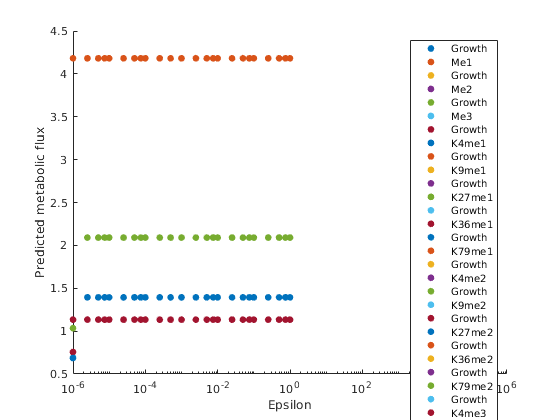

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('Epsilon'); ylabel('Predicted metabolic flux');
legend; 

#### Titrate methionine levels in Methylation model

We'll see the impact of modifying the methionine substrate uptake rate and its impact on methylation.

epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1, 10, 100, 1000];

% Iterate through histone methylation statuses
for i = 1:length(dm_metabolites)
    tmp = eGEM;
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(string(tmp2.rxns) == dm_reactions(i)) = 0.0687;
        
        [~, pos] = ismember({'EX_met_L_e'}, tmp2.rxns);
        tmp2.lb(pos) = -epsilon(j);
        
        % Get metabolic flux
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(string(tmp2.rxns) == dm_reactions(i));
        catch ME
            flux(j, i) = NaN;
        end
        
    end
end

#### Plot methionine titration

Now let's evaluate how the Methionine substrate uptake rate affects histone methylation in RECON1. It looks like the methylation fluxes plateau after -10 umol / gDW*hr.

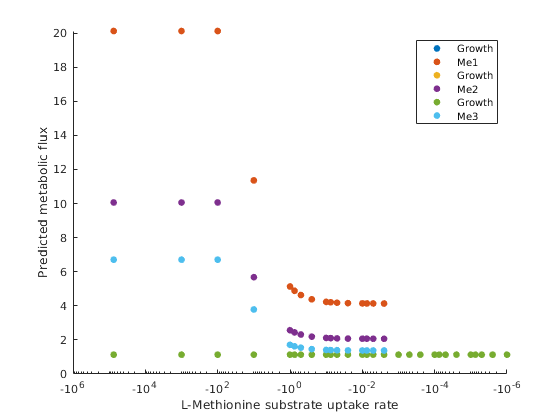

figure;
for i = 1:length(dm_pos)
    hold on;
    scatter(-1*epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(-1*epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('L-Methionine substrate uptake rate'); ylabel('Predicted metabolic flux');
legend; 

## 4. New acetylation model AC2

AC2 contains histone acetylation reactions. So let's perform several experiments to evaluate how well the model can capture methylation flux without transcriptomics.

load /home/scampit/Data/Reconstructions/eGEM/10262020_acetylation;
% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(eGEM.rxns, {'ALR', 'MGSA', 'MGSA2'}));
eGEM.ub(posToTurnOff) = 0; eGEM.lb(posToTurnOff) = 0;

% Set growth rate to be from 0 to 1000
eGEM.lb(3743) = 0;
soln = optimizeCbModel(eGEM);
grate = soln.x(3743)

grate = 1.1339

dm_reactions = ["DM_KACn", ...
                "DM_h3k4ac1_n", "DM_h3k9ac1_n", ...
                "DM_h3k27ac1_n", "DM_h3k36ac1_n", ...
                "DM_h3k79ac1_n"];
dm_metabolites = ["BULK", "K4", "K9", "K27", "K36", "K79"];

#### Titrate different objective coefficients for histone acetylation

We'll evaluate how different epsilon values change the metabolic flux for histone acetylation.

% Different epsilon values to simulate acetylation flux through.
epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1];

% Simulate metabolic fluxes for each  epsilon value   
flux           = zeros(length(epsilon), length(dm_reactions));
grates         = zeros(length(epsilon), length(dm_reactions));

Simulate metabolic fluxes across different epsilon values and the bulk acetylation reaction

% Iterate through histone acetylation statuses
for i = 1:length(dm_reactions)
    tmp = eGEM;
    
    % Iterate through epislon values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        
        % Acetylation reaction in AC1
        tmp2.lb(string(tmp2.rxns) == dm_reactions(i)) = 0;
        tmp2.c(string(tmp2.rxns) == dm_reactions(i)) = epsilon(j);
        
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(string(tmp2.rxns) == dm_reactions(i));
        catch ME
            flux(j, i) = NaN;
        end
    end
end

Let's plot the results for simulating acetylation on the base acetylation model. It looks like acetylation is not particularly sensitive to the epsilon parameter.

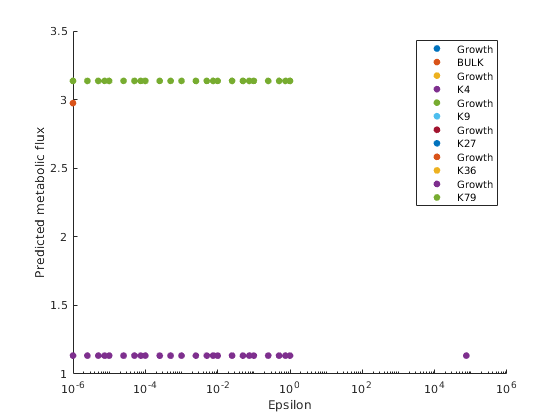

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('Epsilon'); ylabel('Predicted metabolic flux');
legend; 

#### Titrate glucose levels in AC2

We'll see the impact of modifying the methionine substrate uptake rate and its impact on methylation.

epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1, 10, 100, 1000];

% Iterate through histone acetylation statuses
for i = 1:length(dm_metabolites)
    tmp = eGEM;
    
    % Iterate through epison values.
    for j = 1:length(epsilon)
        
        posgluc = find(ismember(tmp.rxns, 'EX_glc_e'));
        tmp.lb(posgluc) = -epsilon(j);
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        tmp2.c(string(tmp2.rxns) == dm_reactions(i)) = 1E-3;
        
        % Get metabolic flux
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(string(tmp2.rxns) == dm_reactions(i));
        catch ME
            flux(j, i) = NaN;
        end
        
    end
end

#### Plot glucose titration

Now let's evaluate how the glucose substrate uptake rate affects histone acetylation in AC1. It looks like the acetylation fluxes plateau after -10 umol / gDW*hr.

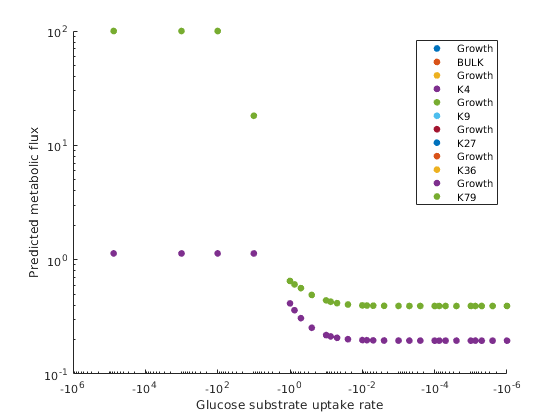

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(-1*epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(-1*epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log', 'YScale', 'log')
xlabel('Glucose substrate uptake rate'); ylabel('Predicted metabolic flux');
legend; 

## 5. Complete eGEM

The complete eGEM contains both histone acetylation and methylation reactions. So let's perform several experiments to evaluate how well the model can capture acetylation and methylation flux without transcriptomics.

load /home/scampit/Data/Reconstructions/eGEM/07132020.mat;
% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(eGEM.rxns, {'ALR', 'MGSA', 'MGSA2'}));
eGEM.ub(posToTurnOff) = 0; eGEM.lb(posToTurnOff) = 0;

% Set growth rate to be from 0 to 1000
eGEM.lb(3743) = 0;
soln = optimizeCbModel(eGEM);
grate = soln.x(3743)

grate = 1.1339

dm_reactions = ["DM_KMe1", "DM_KMe2", "DM_KMe3", ...
                "DM_h3k4me1_n", "DM_h3k9me1_n", ...
                "DM_h3k27me1_n", "DM_h3k36me1_n", ...
                "DM_h3k79me1_n", ...
                "DM_h3k4me2_n", "DM_h3k9me2_n", ...
                "DM_h3k27me2_n", "DM_h3k36me2_n", ...
                "DM_h3k79me2_n", ...
                "DM_h3k4me3_n", "DM_h3k9me3_n", ...
                "DM_h3k27me3_n", "DM_h3k36me3_n", ...
                "DM_h3k79me3_n", ...
                "DM_KACn", ...
                "DM_h3k4ac1_n", "DM_h3k9ac1_n", ...
                "DM_h3k27ac1_n", "DM_h3k36ac1_n", ...
                "DM_h3k79ac1_n"];
            
dm_metabolites = ["Me1", "Me2", "Me3", ...
                  "K4me1", "K9me1", "K27me1", "K36me1", "K79me1",...
                  "K4me2", "K9me2", "K27me2", "K36me2", "K79me2",...
                  "K4me3", "K9me3", "K27me3", "K36me3", "K79me3",...
                  "Ac", ...
                  "K4ac1", "K9ac1", "K27ac1", "K36ac1", "K79ac1"];

#### Titrate different objective coefficients for histone acetylation

We'll evaluate how different epsilon values change the metabolic flux for histone acetylation.

% Different epsilon values to simulate acetylation flux through.
epsilon = [1E-6, 2.5E-6, 5E-6, 7.5E-6, ...
            1E-5, 2.5E-5, 5E-5, 7.5E-5, ...
            1E-4, 2.5E-4, 5E-4, 7.5E4, ...
            0.0010, 0.0025, 0.0050, 0.0075, ...
            0.01, 0.025, 0.05, 0.075, ...
            0.1, .25, 0.5, 0.75, 1];

% Simulate metabolic fluxes for each  epsilon value   
flux           = zeros(length(epsilon), length(dm_reactions));
grates         = zeros(length(epsilon), length(dm_reactions));

Simulate metabolic fluxes across different epsilon values and the bulk acetylation reaction

% Iterate through histone acetylation statuses
for i = 1:length(dm_reactions)
    tmp = eGEM;
    
    % Iterate through epislon values.
    for j = 1:length(epsilon)
        
        % Get baseline growth rate
        [~, soln] = CFR(tmp, hyperparams, {}, {});
        grates(j, i) = soln.x(3743);
        
        % FVA
        tmp2 = tmp;
        tmp2.lb(3743) = soln.x(3743)*0.90;
        tmp2.c(3743) = 0;
        
        % Acetylation reaction in AC1
        tmp2.lb(string(tmp2.rxns) == dm_reactions(i)) = 0;
        tmp2.c(string(tmp2.rxns) == dm_reactions(i)) = epsilon(j);
        
        try
            [~, soln] = CFR(tmp2, hyperparams, {}, {});
            flux(j, i) = soln.x(string(tmp2.rxns) == dm_reactions(i));
        catch ME
            flux(j, i) = NaN;
        end
    end
end

Let's plot the results for simulating acetylation on the base acetylation model. It looks like acetylation is not particularly sensitive to the epsilon parameter.

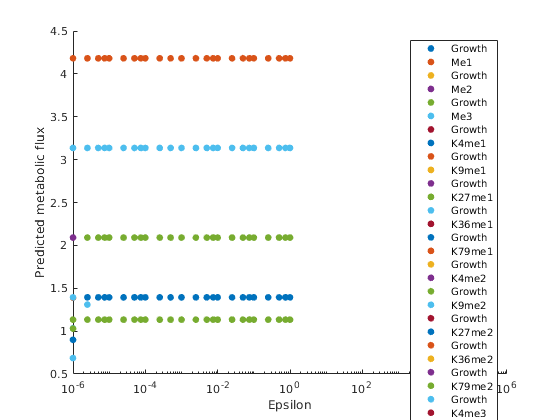

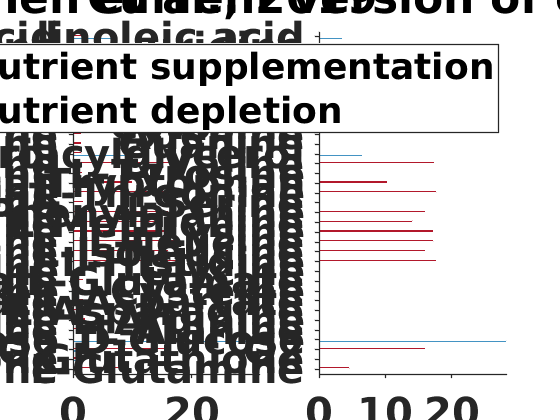

Error using char
Conversion of element 1 from <missing> to character vector is not supported.

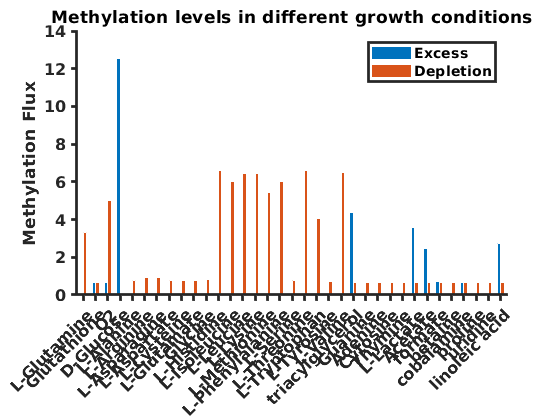

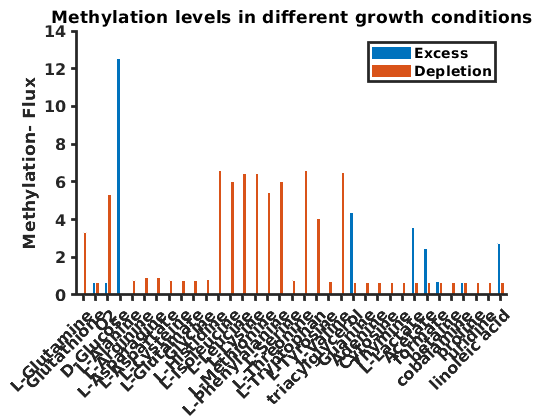

LYSMTF1n	amet_n + peplys_n 	->	ahcys_n + Nmelys_n 
LYSMTF2n_B	2 amet_n + peplys_n 	->	2 ahcys_n + Ndmelys_n 
LYSMTF3n_B	3 amet_n + peplys_n 	->	3 ahcys_n + Ntmelys_n 


HISACYL	accoa_n + peplys_n 	->	coa_n + h_n + Naclys_n 
HISGLCN	peplys_n + uacgam_n 	->	udp_n + Nglclys_n 
UACGAMtn	uacgam_c 	<=>	uacgam_n 
DM_HistAC	accoa_n + Naclys_n 	->	
DM_HistMET	amet_n + Ntmelys_n 	->	
DM_HistGN	uacgam_n + Nglclys_n 	->	
KACYLc	accoa_c + peplys_c 	->	h_c + coa_c + Naclys_c 
EX_peplys	peplys_e 	<=>	peplys_c 


PEPLYStn	peplys_c 	<=>	peplys_n 
DM_KAC	Naclys_n 	->	
DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	
DM_KACcoa	coa_c + coa_n + Naclys_n + Naclys_c 	->	
ACLYn	atp_n + coa_n + cit_n 	->	accoa_n + adp_n + pi_n + oaa_n 
OAAtn	oaa_n 	<=>	oaa_c 
CITtn	cit_n 	<=>	cit_c 
DM_ACCOAn	accoa_n 	->	
DM_COAn	coa_n 	->	
DM_METn	met__L_n 	->	
DM_AMETn	amet_n 	->	
DM_AHCYSn	ahcys_n 	->	
DM_SUCCn	succ_n 	->	
DM_FUMn	fum_n 	->	
DM_CITn	cit_n 	->	
DM_AKGn	akg_n 	->	
DM_MALn	mal__L_n 	->	
DM_OAAn	oaa_n 	->	
DM_PYRn	pyr_n 	->	
DM_FOLn	fol_n 	->	
DM_ATPn	atp_n 	->	
DM_ADPn	adp_n 	->	
DM_NADn	nad_n 	->	
DM_NADHn	nadh_n 	->	
DM_ACn	ac_n 	->	
DM_GLNc	gln__L_c 	->	
DM_THRc	thr__L_c 	->	
DM_GLYBc	glyb_c 	->	
DM_CHOLc	chol_c 	->	
DM_AQCOBALc	aqcobal_c 	->	
METtn	met__L_c 	<=>	met__L_n 
SUCCtn	succ_c 	<=>	succ_n 
FUMtn	fum_c 	<=>	fum_n 
AKGtn	akg_c 	<=>	akg_n 
MALtn	mal__L_c 	<=>	mal__L_n 
PYRtn	pyr_c 	<=>	pyr_n 
Actn	ac_c 	<=>	ac_n 
FALDtn	fald_c 	<=>	fald_n 
METATn	atp_n + h2o_n + met__L_n 	->

grate = 3.1981

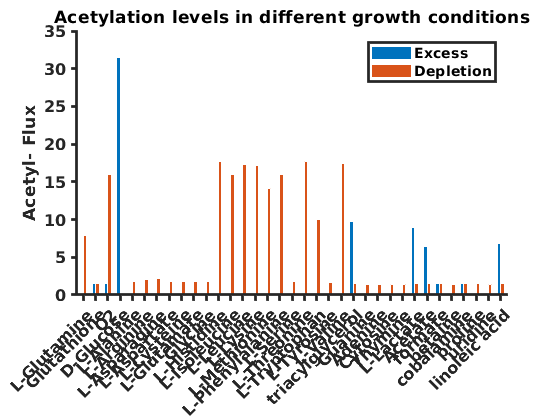

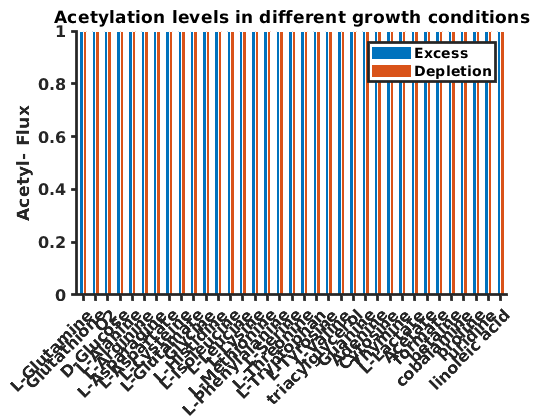

LYSMTF1n	amet_n + peplys_n 	->	Nmelys_n + ahcys_n 
LYSMTF2n_B	2 amet_n + peplys_n 	->	2 ahcys_n + Ndmelys_n 
LYSMTF3n_B	3 amet_n + peplys_n 	->	3 ahcys_n + Ntmelys_n 
LYSMTF2n_A	amet_n + Nmelys_n 	->	ahcys_n + Ndmelys_n 
LYSMTF3n_A	amet_n + Ndmelys_n 	->	ahcys_n + Ntmelys_n 
HISACYL	accoa_n + peplys_n 	->	coa_n + h_n + Naclys_n 
HISGLCN	peplys_n + uacgam_n 	->	udp_n + Nglclys_n 
UACGAMtn	uacgam_c 	<=>	uacgam_n 
DM_HistAC	accoa_n + Naclys_n 	->	
DM_HistMET	amet_n + Ntmelys_n 	->	
DM_HistGN	uacgam_n + Nglclys_n 	->	
KACYLc	accoa_c + peplys_c 	->	h_c + coa_c + Naclys_c 
EX_peplys	peplys_e 	<=>	peplys_c 
PEPLYStn	peplys_c 	<=>	peplys_n 
DM_KAC	Naclys_n 	->	
DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	
DM_KACcoa	coa_c + coa_n + Naclys_n + Naclys_c 	->	
ACLYn	atp_n + coa_n + cit_n 	->	accoa_n + adp_n + pi_n + oaa_n 
OAAtn	oaa_n 	<=>	oaa_c 
CITtn	cit_n 	<=>	cit_c 
DM_ACCOAn	accoa_n 	->	
DM_COAn	coa_n 	->	
DM_METn	met__L_n 	->	
DM_AMETn	amet_n 	->	
DM_AHCYSn	ahcys_n 	->	

DM_GLYBc	glyb_c 	->	


DM_AQCOBALc	aqcobal_c 	->	
METtn	met__L_c 	<=>	met__L_n 
SUCCtn	succ_c 	<=>	succ_n 
FUMtn	fum_c 	<=>	fum_n 
AKGtn	akg_c 	<=>	akg_n 
MALtn	mal__L_c 	<=>	mal__L_n 
PYRtn	pyr_c 	<=>	pyr_n 
Actn	ac_c 	<=>	ac_n 
FALDtn	fald_c 	<=>	fald_n 
METATn	atp_n + h2o_n + met__L_n 	->	ppi_n + pi_n + amet_n 
LSD_DML2n	h2o_n + o2_n + Ndmelys_n + fad_n 	->	h2o2_n + Nmelys_n + fald_n + fadh2_n 
LSD_DML1n	h2o_n + o2_n + fad_n + Nmmelys_n 	->	h2o2_n + peplys_n + fald_n + fadh2_n 
JMJ_DMT3n	o2_n + Ntmelys_n + akg_n + fe2_n 	->	Ndmelys_n + succ_n + fald_n + co2_n + fe3_n 
JMJ_DMT2n	o2_n + Ndmelys_n + akg_n + fe2_n 	->	Nmelys_n + succ_n + fald_n + co2_n + fe3_n 
JMJ_DMT1n	o2_n + Nmelys_n + akg_n + fe2_n 	->	peplys_n + succ_n + fald_n + co2_n + fe3_n 
ACSS2n	atp_n + coa_n + ac_n 	->	accoa_n + ppi_n + amp_n 
PDHn	coa_n + nad_n + pyr_n 	->	accoa_n + nadh_n + co2_n 
ADPtn	adp_n 	<=>	adp_c 


AMPtn	amp_n 	<=>	amp_c 


grate = 755.0032

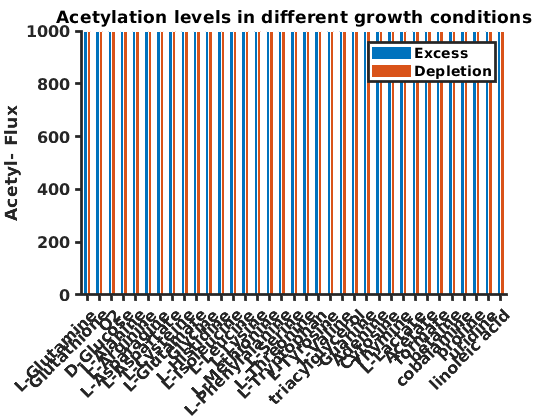

figure;
for i = 1:length(dm_metabolites)
    hold on;
    scatter(epsilon, grates(:, i), [], 'filled', ...
            'DisplayName', 'Growth');
    hold off;
    
    hold on;
    scatter(epsilon, flux(:, i), [], 'filled', ...
            'DisplayName', char(string(dm_metabolites(i))));
    hold off;
end
set(gca, 'XScale', 'log')
xlabel('Epsilon'); ylabel('Predicted metabolic flux');
legend; 